# Face classification: investigating patch size

The `simpleFaceRecognition()` function, below, uses HOG features to represent images of faces in a classification problem. As you know from lectures: choosing the size of HOG features involves considering a tradeoff. The smaller the feature size, the more structural information is captured. However, this also increases the dimensionality of the feature space which can reduce classifier performance and increase execution times. The challenge here is to investigate this tradeoff:

Marks are available for:

- Finding the default patch size used by `extractHOGFeatures()` and recording it in a comment [2 marks]

- Finding the dimensionality of the feature space that results from the face images and recording it in a comment [2 marks]

- Looking at the "matched class" images to find the total number of misclassifications for the first 5 people and recording your answer in a comment [2 marks]

- Measuring how long the `simpleFaceRecognition()` function takes to execute and recording it in a comment [2 marks]

- Adding a local variable called `patch_size` to the top of the `simpleFaceRecognition()` function which can be used to vary the size of the HOG features [8 marks]

- Measuring how long the `simpleFaceRecognition()` function takes to execute when using HOG features of size 24*24 pixels and recording it in a comment [2 marks]

- Looking at the "matched class" images to find the total number of misclassifications for the first 5 people and recording your answer in a comment [2 marks]

[20 marks]

patch_size =     24    24


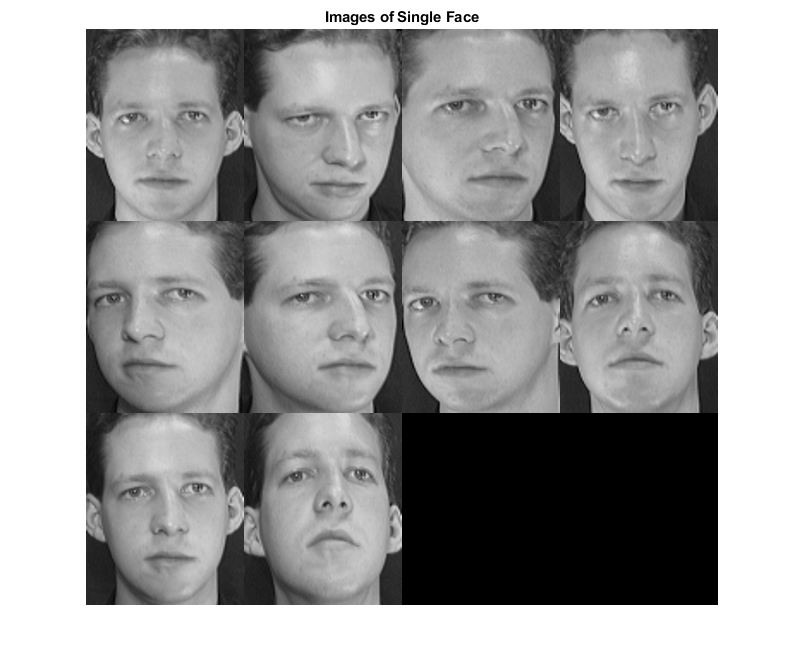

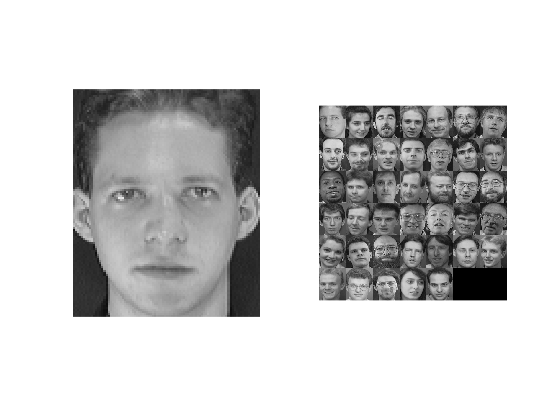

ans = 216

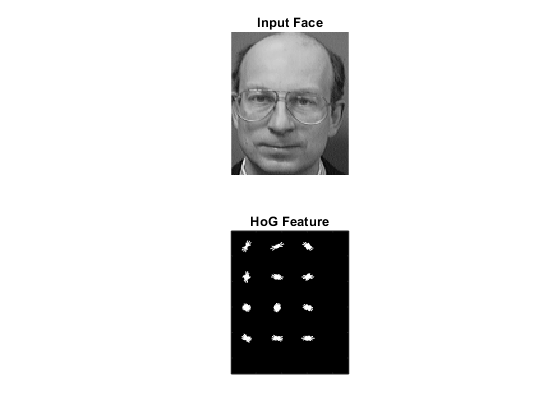

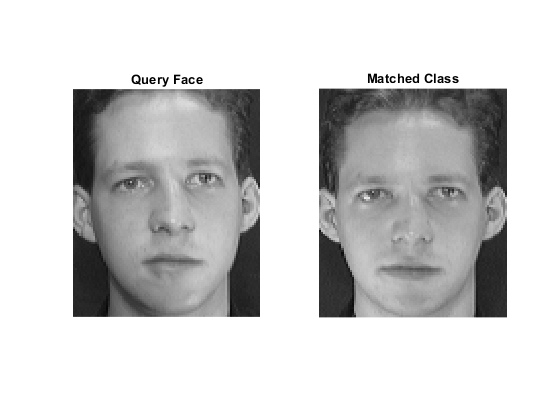

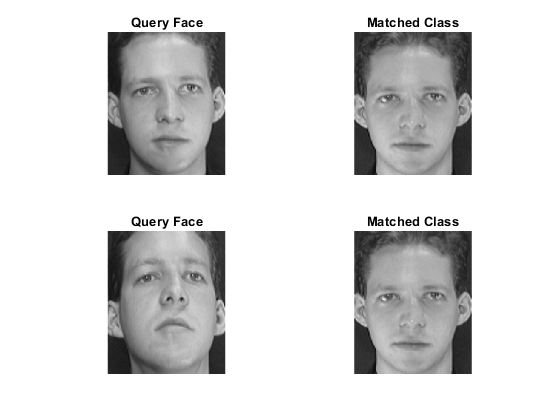

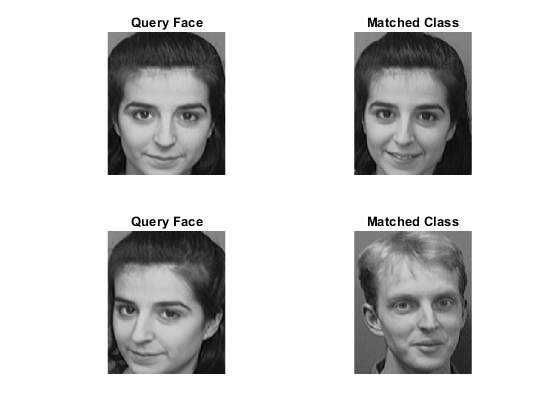

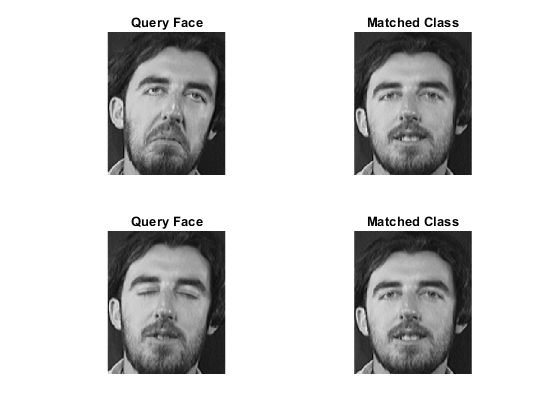

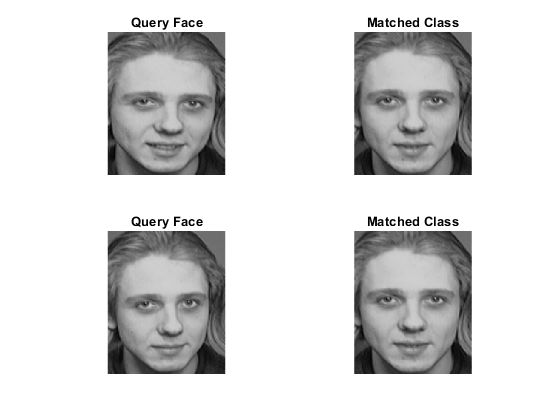

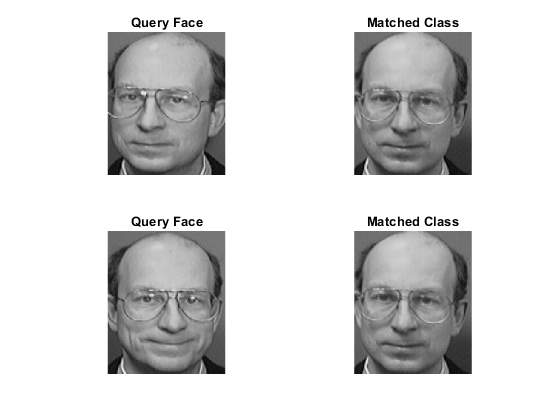

% add as many comments/lines of code as you need below:

% 1. Patch size - 8x8
% 2. Dimensionality of feature space - 4680 using length(hogFeature)
% 3. Total number of misclassifications - 1
% 4. time taken to complete function = 26.4092
% 6. time taken to complete function (24x24 HOG feature size) = 26.4088
% 7. Total number of misclassifications - 1
tic; % start timer
simpleFaceRecognition(24) % call the function

time_taken = toc; % end timer and assign to time_taken variable
time_taken

time_taken = 47.1068

function simpleFaceRecognition(cell_size)

%% Simple Face Recognition Example
%  Copyright 2014-2015 The MathWorks, Inc.
patch_size = [cell_size cell_size]
%% Load Image Information from ATT Face Database Directory
faceDatabase = imageSet('FaceDatabaseATT','recursive');
%% Display Montage of First Face
figure;
montage(faceDatabase(1).ImageLocation);
title('Images of Single Face');
%%  Display Query Image and Database Side-Side
personToQuery = 1;
galleryImage = read(faceDatabase(personToQuery),1);
figure;
for i=1:size(faceDatabase,2)
imageList(i) = faceDatabase(i).ImageLocation(5);
end
subplot(1,2,1);imshow(galleryImage);
subplot(1,2,2);montage(imageList);
diff = zeros(1,9);
%% Split Database into Training & Test Sets
[training,test] = partition(faceDatabase,[0.8 0.2]);
%% Extract and display Histogram of Oriented Gradient Features for single face 
person = 5;
[hogFeature, visualization]= ...
    extractHOGFeatures(read(training(person),1), 'CellSize', patch_size);
length(hogFeature)
figure;
subplot(2,1,1);imshow(read(training(person),1));title('Input Face');
subplot(2,1,2);plot(visualization);title('HoG Feature');
%% Extract HOG Features for training set 
trainingFeatures = zeros(size(training,2)*training(1).Count,4680);
featureCount = 1;
for i=1:size(training,2)
    for j = 1:training(i).Count
        trainingFeatures(featureCount,:) = extractHOGFeatures(read(training(i),j));
        trainingLabel{featureCount} = training(i).Description;    
        featureCount = featureCount + 1;
    end
    personIndex{i} = training(i).Description;
end
%% Create 40 class classifier using fitcecoc 
faceClassifier = fitcecoc(trainingFeatures,trainingLabel);
%% Test Images from Test Set 
person = 1;
queryImage = read(test(person),1);
queryFeatures = extractHOGFeatures(queryImage);
personLabel = predict(faceClassifier,queryFeatures);
% Map back to training set to find identity 
booleanIndex = strcmp(personLabel, personIndex);
integerIndex = find(booleanIndex);
figure;
subplot(1,2,1);imshow(queryImage);title('Query Face');
subplot(1,2,2);imshow(read(training(integerIndex),1));title('Matched Class');
%% Test First 5 People from Test Set
figure;
figureNum = 1;
for person=1:5
    for j = 1:test(person).Count
        queryImage = read(test(person),j);
        queryFeatures = extractHOGFeatures(queryImage);
        personLabel = predict(faceClassifier,queryFeatures);
        % Map back to training set to find identity
        booleanIndex = strcmp(personLabel, personIndex);
        integerIndex = find(booleanIndex);
        subplot(2,2,figureNum);imshow(imresize(queryImage,3));title('Query Face');
        subplot(2,2,figureNum+1);imshow(imresize(read(training(integerIndex),1),3));title('Matched Class');
        figureNum = figureNum+2;
        
    end
    figure;
    figureNum = 1;
end

end